## 1. Defining quantum circuits

Quantum Circuit can be created in following ways:

[`c =` `quantumCircuit``(numQubits)`](https://in.mathworks.com/help/matlab/ref/quantumcircuit.html?searchHighlight=quantumcircuit&s_tid=srchtitle_support_results_1_quantumcircuit#d126e1306113)

[`c =` `quantumCircuit``(gates)`](https://in.mathworks.com/help/matlab/ref/quantumcircuit.html?searchHighlight=quantumcircuit&s_tid=srchtitle_support_results_1_quantumcircuit#d126e1306132)

[`c =` `quantumCircuit``(gates,numQubits)`](https://in.mathworks.com/help/matlab/ref/quantumcircuit.html?searchHighlight=quantumcircuit&s_tid=srchtitle_support_results_1_quantumcircuit#d126e1306156)

[`c =` `quantumCircuit``(``___``,Name=name)`](https://in.mathworks.com/help/matlab/ref/quantumcircuit.html?searchHighlight=quantumcircuit&s_tid=srchtitle_support_results_1_quantumcircuit#d126e1306174)

To create a three-qubit GHZ state, firstly all the gates have to be defined before calling the quantumCircuit.

gates = [hGate(1);cxGate(1,2);cxGate(2,3)];
circ = quantumCircuit(gates, Name= "circuit");

To plot the Quantum Circuit

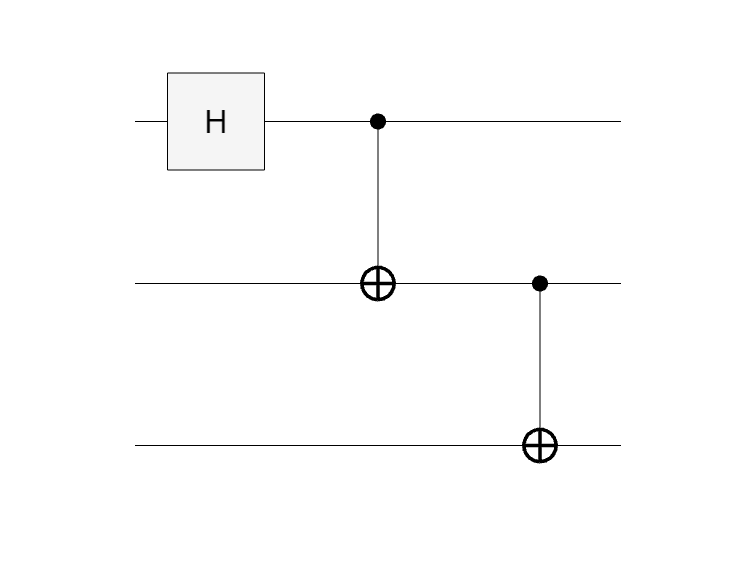

plot(circ)

## 2. Obtaining the unitary representation, get the statevector and run on MATLAB simulator. 

To get the unitary matrix of the three-qubit GHZ state using the fuction *getMatrix*.

getMatrix(circ)

ans =     0.7071         0         0         0    0.7071         0         0         0
         0    0.7071         0         0         0    0.7071         0         0
         0         0         0    0.7071         0         0         0    0.7071
         0         0    0.7071         0         0         0    0.7071         0
         0         0    0.7071         0         0         0   -0.7071         0
         0         0         0    0.7071         0         0         0   -0.7071
         0    0.7071         0         0         0   -0.7071         0         0
    0.7071         0         0         0   -0.7071         0         0         0


% Let do a quick check of the unitarity of a matrix
U = getMatrix(circ);
% U'*U - I = 0
round(norm(U'*U - eye(8)))

ans = 0

To run the circuit on a simulator we first have to define the *simulate* function.

state = simulate(circ);   

To get the statevector representation in computational basis of the three-qubit GHZ state we use the prepared quantum *state* with the function *formula*.

formula(state)

ans =     "0.70711 * |000> +
     0.70711 * |111>"


% To represent the same state in hadamard basis
formula(state,Basis="X")

ans =     "0.5 * |+++> +
     0.5 * |+--> +
     0.5 * |-+-> +
     0.5 * |--+>"


To simulate running the quantum circuit, we now use the prepared quantum *state* with the function *randsample* and specify number of shorts.

% inputs to the function below are the state and the number of shorts
M = randsample(state,1000);
T = table(M.MeasuredStates, M.Counts, VariableNames=["States","Counts"])

T = 2×2 table
    States    Counts
    ______    ______

    "000"      499  
    "111"      501  


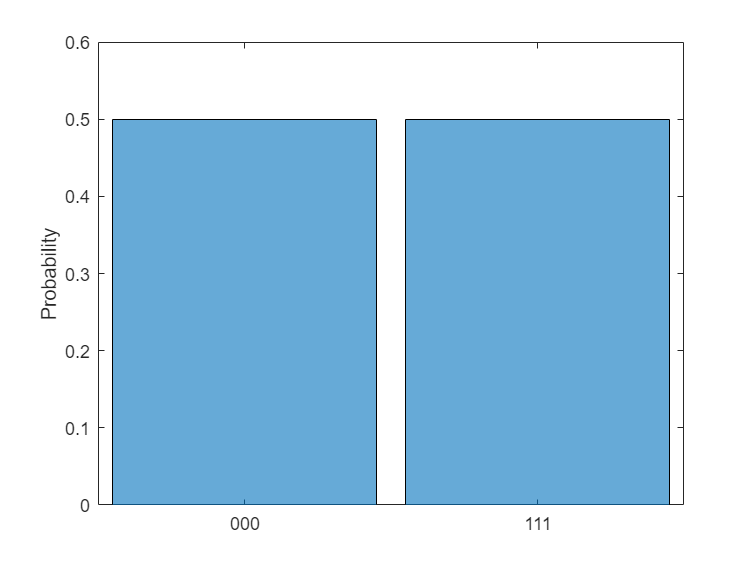

% Plot the results on a histogram 
histogram(state)

## 3. Create a circuit by appending circuits together using *compositeGate*:

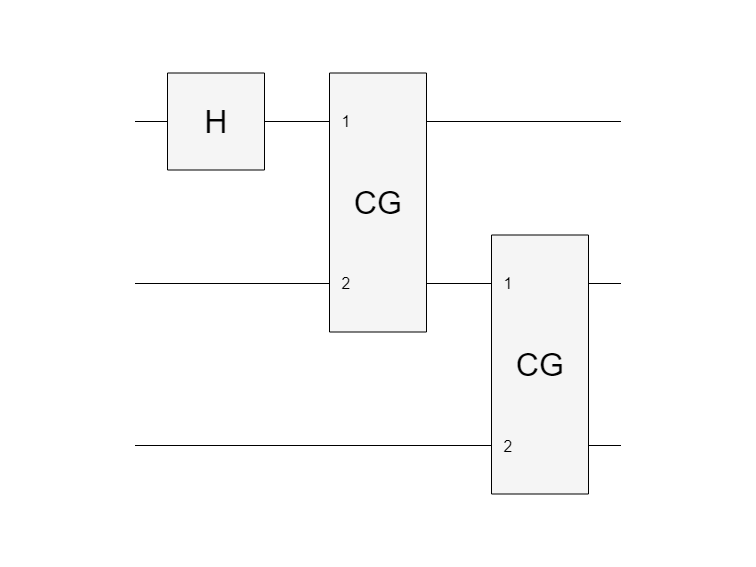

cnot_custom = [cxGate(1,2)];
qc_inner = quantumCircuit(cnot_custom);
gates_appended = [hGate(1) compositeGate(qc_inner,[1 2]) compositeGate(qc_inner,[2 3])];
circ = quantumCircuit(gates_appended);
plot(circ)

Let's decompose the circuit and plot

plot(unpack(circ, "recursive"))

## 4. Let us now look at few examples:

- Implement the statevector representation of all four bell states.

% First create the circuit for bell states
gates = [hGate(1); cxGate(1,2)];
bell = quantumCircuit(gates);

Initialize a quantum state with different output to create all bell states during simulation.

% display all the possible bell quantum state
% important convention to note here is that in '10' the top or first qubit is 1
ket = ["00","01","10","11"];
for i = 1:length(ket)
    state = simulate(bell, quantum.gate.QuantumState(ket(i)));
    formula(state)
end

ans =     "0.70711 * |00> +
     0.70711 * |11>"


ans =     "0.70711 * |01> +
     0.70711 * |10>"


ans =     "0.70711  * |00> +
     -0.70711 * |11>"


ans =     "0.70711  * |01> +
     -0.70711 * |10>"


- Procedural circuit for generation

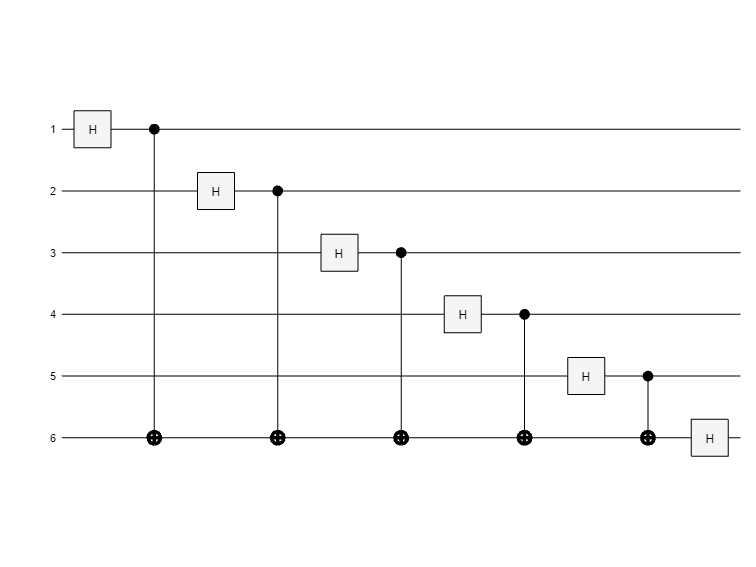

% Example of circuit generation with gates in loop
numQubits = 6;
gates = [];
for i=1:numQubits
    gates = [gates; hGate(i)];
    if i ~= numQubits
        gates = [gates;cxGate(i, numQubits)];
    end
end
qc = quantumCircuit(gates,numQubits);
plot(qc)

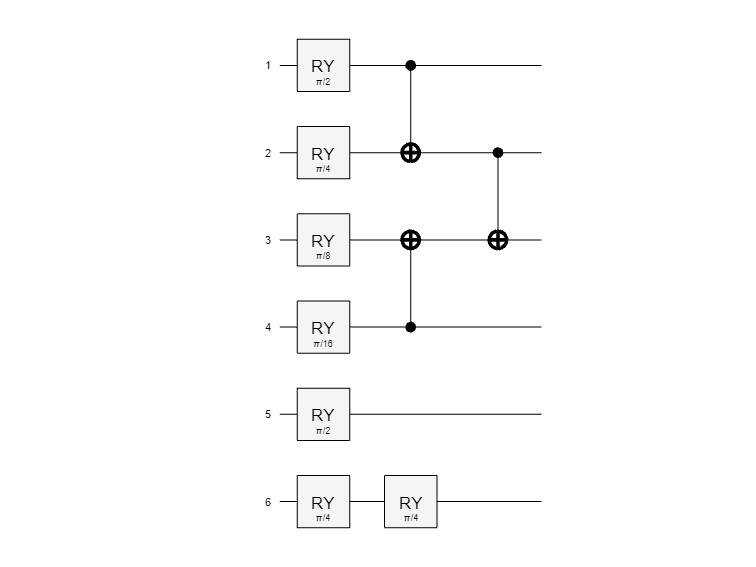

% Another example of circuit generation with different phases
weights = [pi/2,pi/4,pi/8,pi/16,pi/2,pi/4];
numQubits = 6;
readout = 6;
paramGates = [ryGate(1:numQubits, weights(1:numQubits))
              cxGate([1 4], [2 3])
              ryGate(2, weights(numQubits:end-1))
              cxGate(2,3)
              ryGate(readout, weights(end))
              ];
circ = quantumCircuit(paramGates);
plot(circ)

- Implement the algorithum N-bit Quantum Fourier Transform (QFT) circuit

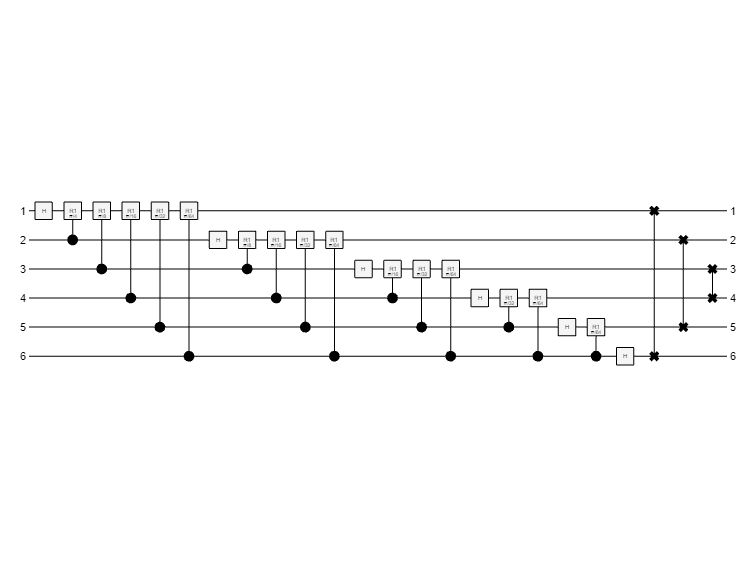

% The function myQFT is defined at the end of the notebook
qc = myQFT(6);
plot(qc)

The same implemenation can be acheived using the *qftGate *directly`.`

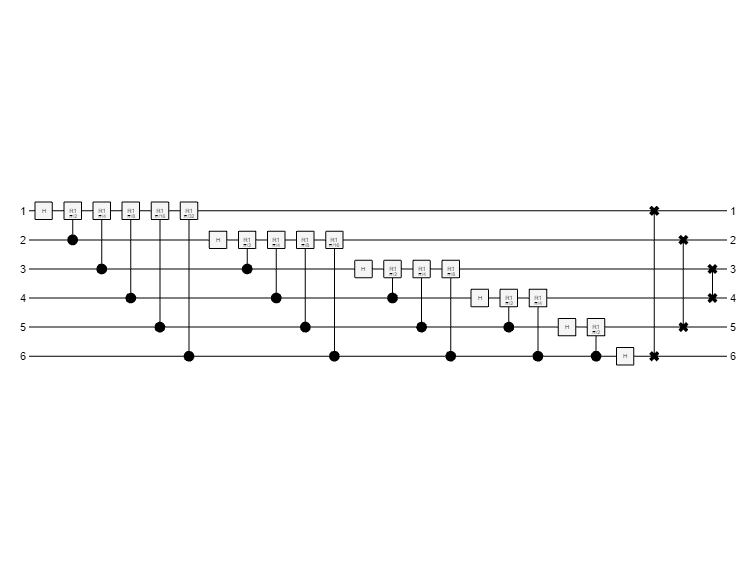

cg = qftGate(1:6);
plot(cg)

## Functions used in the notebook

function qc = myQFT(n_qubits)
    gates = [];
    for i=1:n_qubits
        gate_1 = hGate(i);
        gates = [gates;gate_1];
        for j=i:n_qubits
            if (i ~= j)
                gate_1 = cr1Gate(j, i, pi./2.^j);
                gates = [gates;gate_1];
            end
    
        end
    end
    for i=1:floor(n_qubits/2)
        gate_1 = swapGate(i, n_qubits + 1 - i);
        gates = [gates;gate_1];
    end
    qc = quantumCircuit(gates,n_qubits);
end